T2_total = readtable('gly.xlsx', 'Sheet','T2_total')

T2_total = 10240×2 table
       Time       CHAN1
    __________    _____

     -0.004072       0 
    -0.0040712       0 
    -0.0040704       0 
    -0.0040696       0 
    -0.0040688       0 
     -0.004068       0 
    -0.0040672       0 
    -0.0040664       0 
    -0.0040656    0.08 
    -0.0040648       0 
     -0.004064       0 
    -0.0040632       0 
    -0.0040624       0 
    -0.0040616       0 
    -0.0040608       0 
      -0.00406       0 


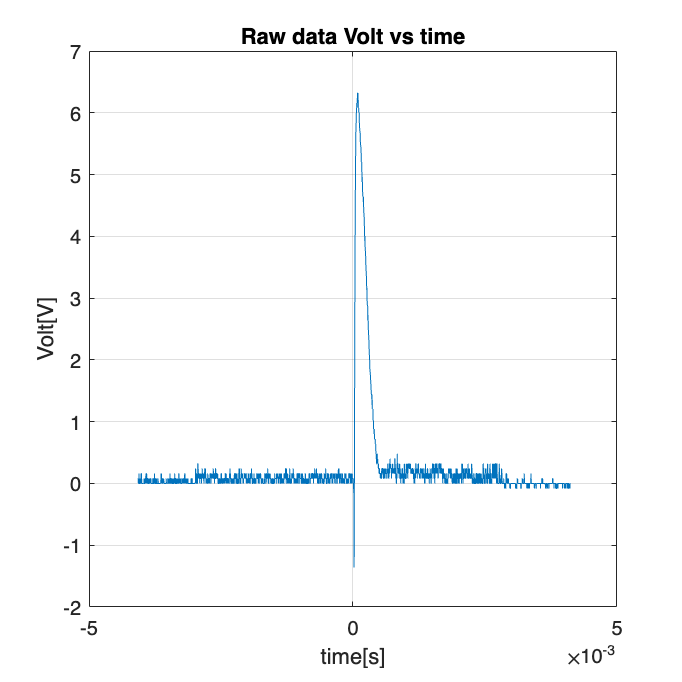

figure;
set(gcf,'position',[0,0,1000,1000])
time=T2_total.Time;
Volt = T2_total.CHAN1;
plot(time,Volt)

ylabel('Volt[V]')
xlabel('time[s]')
title('Raw data Volt vs time')



k = find(time>0);
time=time(k);
Volt=Volt(k);


grid on

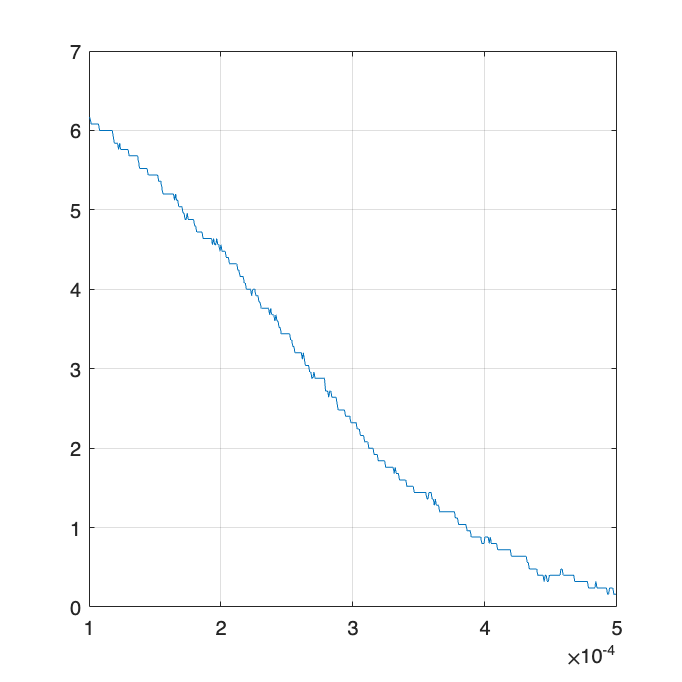


time_start =0.1e-3;
time_end = 0.5e-3;

k = find((time>time_start)&(time < time_end));
time=time(k);
Volt=Volt(k);





% k = find((Volt>0));
% time=time(k);
% Volt=Volt(k)-min(Volt);



% Volt = smooth(Volt);
plot(time,Volt)


grid on

x=time;
y=Volt;
delta_y=Volt.*0+0.1;
delta_x=time.*0+0.00001;

T = table(x,delta_x,y,delta_y)

T = 500×4 table
        x        delta_x     y      delta_y
    _________    _______    ____    _______

       0.0001     1e-05     6.16      0.1  
    0.0001008     1e-05     6.16      0.1  
    0.0001016     1e-05     6.08      0.1  
    0.0001024     1e-05     6.08      0.1  
    0.0001032     1e-05     6.08      0.1  
     0.000104     1e-05     6.08      0.1  
    0.0001048     1e-05     6.08      0.1  
    0.0001056     1e-05     6.08      0.1  
    0.0001064     1e-05     6.08      0.1  
    0.0001072     1e-05     6.08      0.1  
     0.000108     1e-05        6      0.1  
    0.0001088     1e-05        6      0.1  
    0.0001096     1e-05        6      0.1  
    0.0001104     1e-05        6      0.1  
    0.0001112     1e-05        6      0.1  
     0.000112     1e-05        6      0.1  


writetable(T,'T2_totalgly.xlsx') 

% createFit2(x, y)